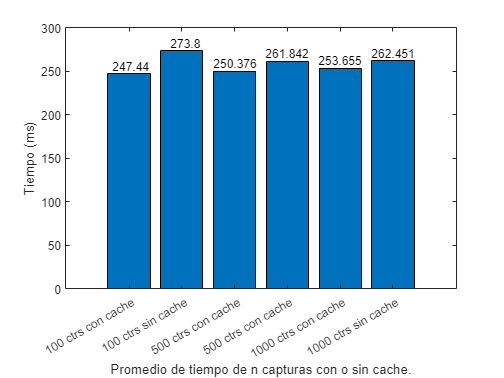


sr500 = sum(randomTimes500{:,:});
sc500 = sum(cacheTimes500{:,:});
sr100 = sum(randomTimes100{:,:});
sc100 = sum(cacheTimes100{:,:});
sr1000 = sum(randomTimes1000{:,:});
sc1000 = sum(cacheTimes1000{:,:});

pr500 = mean(randomTimes500{:,:});
pc500 = mean(cacheTimes500{:,:});
pr100 = mean(randomTimes100{:,:});
pc100 = mean(cacheTimes100{:,:});
pr1000 = mean(randomTimes1000{:,:});
pc1000 = mean(cacheTimes1000{:,:});


c500 = sum(redisCalls500 {:,:} == 1);
c100 = sum(redisCalls100{:,:} == 1);
c1000 = sum(redisCalls1000{:,:} == 1);


tabla = table(pc100, pr100,pc500,pr500,pc1000,pr1000);
bar(table2array(tabla));


text(1:length(table2array(tabla)), table2array(tabla), num2str(table2array(tabla)'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
xticklabels({'100 ctrs con cache', '100 ctrs sin cache', '500 ctrs con cache', '500 ctrs con cache','1000 ctrs con cache', '1000 ctrs sin cache'});
ylabel('Tiempo (ms)');
xlabel('Promedio de tiempo de n capturas con o sin cache.');

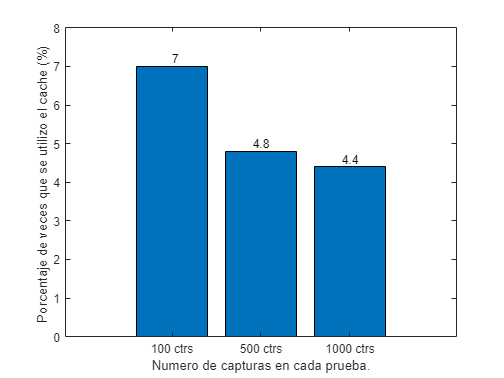

error100 = (c100/100) *100;
error500 = (c500/500) *100;
error1000 = (c1000/1000)*100;

tabla1 = table(error100, error500,error1000);
bar(table2array(tabla1));


text(1:length(table2array(tabla1)), table2array(tabla1), num2str(table2array(tabla1)'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
xticklabels({'100 ctrs', '500 ctrs', '1000 ctrs'});
ylabel('Porcentaje de veces que se utilizo el cache (%) ');
xlabel('Numero de capturas en cada prueba.');

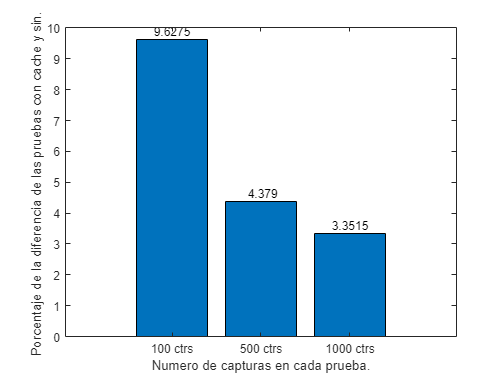

errorp100 = ((pr100-pc100)/pr100) *100;
errorp500 = ((pr500-pc500)/pr500) *100;
errorp1000 = ((pr1000-pc1000)/pr1000) *100;

tabla2 = table(errorp100, errorp500,errorp1000);
bar(table2array(tabla2));

text(1:length(table2array(tabla2)), table2array(tabla2), num2str(table2array(tabla2)'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
xticklabels({'100 ctrs', '500 ctrs', '1000 ctrs'});
ylabel('Porcentaje de la diferencia de las pruebas con cache y sin. ');
xlabel('Numero de capturas en cada prueba.');

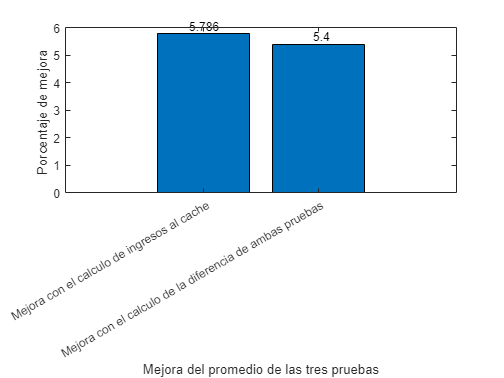

numprom =  (errorp100 + errorp1000 + errorp500) / 3;
difprom =  (error500 + error100 + error1000) / 3;

tabla3 = table(numprom,difprom);
bar(table2array(tabla3));

text(1:length(table2array(tabla3)), table2array(tabla3), num2str(table2array(tabla3)'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
xticklabels({'Mejora con el calculo de ingresos al cache', 'Mejora con el calculo de la diferencia de ambas pruebas'});
ylabel('Porcentaje de mejora ');
xlabel('Mejora del promedio de las tres pruebas');